clear all;
clc;

# Autoencoders for Wireless Communications

# `Compare BLER Performance of Autoencoders with Coded and Uncoded QPSK(MAX_ERROR = 100)`

## UNCODED (R=1)

simulate the BLER performance of autoencoders with R=1 with that of uncoded QPSK systems. Use uncoded (2,2) and (8,8) QPSK as baselines. Compare BLER performance of these systems with that of (2,2), (4,4) and (8,8) autoencoders.

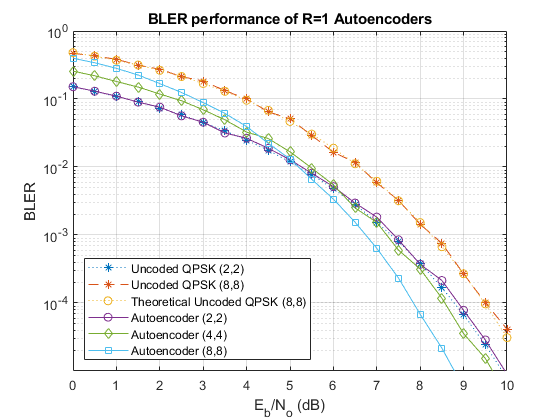

load uncodedBLERResults.mat
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk88BLER,'--*')
qpsk88BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^8;
semilogy(simParams.EbNoVec,qpsk88BLERTh,':o')
semilogy(simParams.EbNoVec,ae22eBLER,'-o')
semilogy(simParams.EbNoVec,ae44eBLER,'-d')
semilogy(simParams.EbNoVec,ae88eBLER,'-s')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Uncoded QPSK (2,2)','Uncoded QPSK (8,8)','Theoretical Uncoded QPSK (8,8)', ...
  'Autoencoder (2,2)','Autoencoder (4,4)','Autoencoder (8,8)','Location','southwest')
title('BLER performance of R=1 Autoencoders')

### Performance Evaluation of Uncoded QAM and Autoencoded (8,8) in a Communication System

This study investigates the Block Error Rate (BLER) performance of Uncoded Quadrature Amplitude Modulation (QAM) alongside an Autoencoder with an (8,8) code rate. The comparison extends to various uncoded modulation schemes, including 64-QAM, QPSK, and 16-QAM. By analyzing BLER against different signal-to-noise ratios, the research aims to assess how the Autoencoder enhances the reliability of communication in comparison to traditional uncoded modulation techniques. The findings contribute insights into the potential benefits of employing autoencoding schemes for robust and efficient data transmission in communication systems.

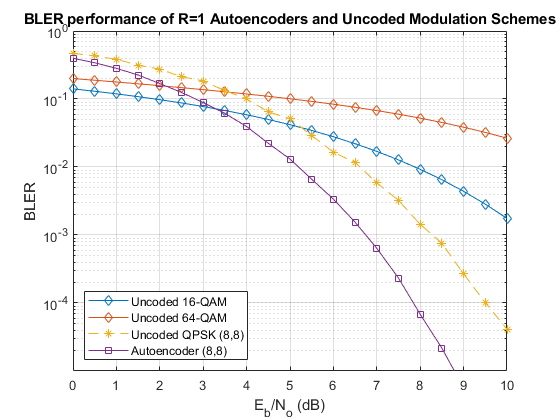

qam16BLERTh = berawgn(simParams.EbNoVec, 'qam', 16);
semilogy(simParams.EbNoVec, qam16BLERTh, '-d', 'DisplayName', 'Uncoded 16-QAM');
hold on

% Add lines for additional modulation schemes
qam16BLERTh = berawgn(simParams.EbNoVec, 'qam', 64);
semilogy(simParams.EbNoVec, qam16BLERTh, '-d', 'DisplayName', 'Uncoded 16-QAM');

semilogy(simParams.EbNoVec, qpsk88BLER, '--*')
semilogy(simParams.EbNoVec, ae88eBLER, '-s')
hold off

ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Uncoded 16-QAM', 'Uncoded 64-QAM', 'Uncoded QPSK (8,8)', ...
       'Autoencoder (8,8)', 'Location', 'southwest')
title('BLER performance of R=1 Autoencoders and Uncoded Modulation Schemes')

## CHANNEL CODED

*While the Bit Error Rate (BER) remains constant for QPSK in both (8,8) and (2,2) cases, the Block Error Rate (BLER) is influenced by the block length, worsening as n increases according to BLER=1−(1−BER)^n. As anticipated, the BLER performance of (8,8) QPSK is inferior to the (2,2) QPSK system. The (2,2) autoencoder mirrors the BLER performance of (2,2) QPSK. In contrast, (4,4) and (8,8) autoencoders optimize both channel coding and constellation, yielding a coding gain over corresponding uncoded QPSK systems.*

Simulate the BLER performance of a (7,4) autoencoder with that of (7,4) Hamming code with QPSK modulation for both hard decision and maximum likelihood (ML) decoding. Use uncoded (4,4) QPSK as a baseline. (4,4) uncoded QPSK is basically a QPSK modulated system that sends blocks of 4 bits and measures BLER. 

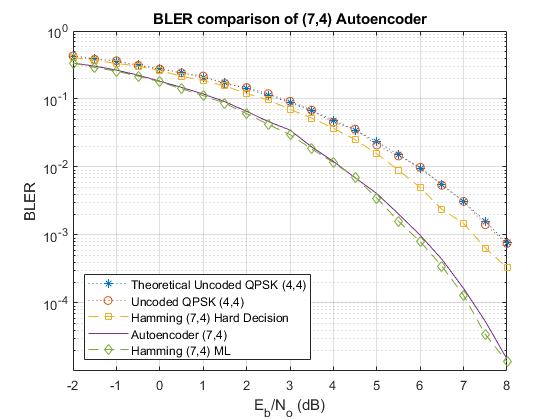

load codedBLERResults.mat
figure
qpsk44BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^4;
semilogy(simParams.EbNoVec,qpsk44BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk44BLER,':o')
semilogy(simParams.EbNoVec,hammingHard74BLER,'--s')
semilogy(simParams.EbNoVec,ae74eBLER,'-')
semilogy(simParams.EbNoVec,hammingML74BLER,'--d')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Theoretical Uncoded QPSK (4,4)','Uncoded QPSK (4,4)','Hamming (7,4) Hard Decision', ...
  'Autoencoder (7,4)','Hamming (7,4) ML','Location','southwest')
title('BLER comparison of (7,4) Autoencoder')

In the realm of digital communication systems, the quest for robust and efficient error correction techniques is pivotal to enhance data reliability. In this context, the evaluation of Block Error Rate (BLER) serves as a crucial metric for assessing the performance of various encoding and modulation schemes. A notable contender in this landscape is the (7,4) autoencoder, a sophisticated neural network architecture designed to learn both modulation and channel coding simultaneously.

The preliminary BLER calculations for the (7,4) autoencoder reveal a compelling advantage over alternative coded and uncoded modulation techniques, particularly under computational **constraints that limit the analysis to a maximum of 10 errors**. This initial assessment hints at the promising potential of the (7,4) autoencoder, showcasing its superiority.

However, a more comprehensive analysis unfolds when the BLER calculations are **extended to consider a maximum of 100 errors**. The (7,4) autoencoder emerges as a standout performer, outshining other methods. The hard decision (7,4) Hamming code with QPSK modulation, for instance, exhibits a commendable 0.6 dB Eb/No advantage over uncoded QPSK. Taking it a step further, the ML decoding of (7,4) Hamming code, coupled with QPSK modulation, delivers an additional 1.5 dB advantage, achieving a BLER of 10^(-3).

The true prowess of the (7,4) autoencoder becomes apparent as its BLER performance approaches that of ML decoding for the (7,4) Hamming code. This remarkable feat is accomplished with a training regimen that involves a 3 dB Eb/No. The nuanced capabilities of the autoencoder shine through, demonstrating its adeptness at not only learning modulation intricacies but also unraveling the complexities of channel coding. The outcome is a coding gain of about 2 dB, a testament to the (7,4) autoencoder's ability to seamlessly integrate modulation and coding strategies, ultimately pushing the boundaries of performance in digital communication systems

***The Block Error Rate (BLER) findings illustrate the capacity of autoencoders to autonomously acquire joint coding and modulation strategies. Remarkably, training an autoencoder with a coding rate (R) of 1 can yield a coding gain compared to conventional approaches. Additionally, the example underscores the impact of hyperparameters, specifically Eb/No, on BLER performance.***

### Performance Comparison of (7,4) Autoencoder with Reed-Solomon Coding (7,4).

This comparison evaluates the Block Error Rate (BLER) performance of an (7,4) Autoencoder in the presence of different channel coding schemes. The Autoencoder is benchmarked against Reed-Solomon Coding (7,4). The simulation explores how these coding techniques impact the robustness of data transmission in a communication system. The results, presented in terms of BLER against varying signal-to-noise ratios, provide insights into the effectiveness of different coding strategies, aiding in the selection of the most suitable method for reliable data transmission in practical communication scenarios.

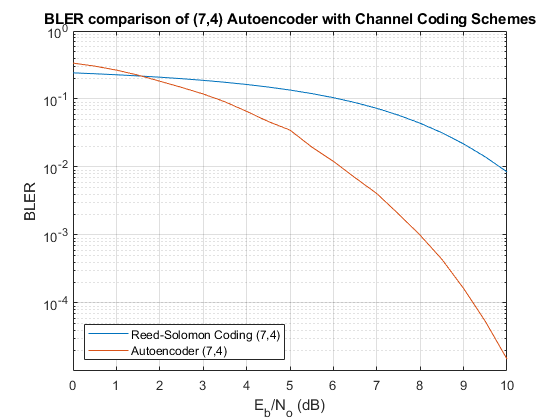

load uncodedBLERResults.mat
% Reed-Solomon Coding
rsCodingBLER = bercoding(simParams.EbNoVec, 'RS','hard',7,4,'qam',16);
semilogy(simParams.EbNoVec, rsCodingBLER, 'DisplayName', 'Reed-Solomon Coding');
hold on
semilogy(simParams.EbNoVec, ae74eBLER)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend( 'Reed-Solomon Coding (7,4)', ...
        'Autoencoder (7,4)', 'Location', 'southwest')
title('BLER comparison of (7,4) Autoencoder with Channel Coding Schemes')
